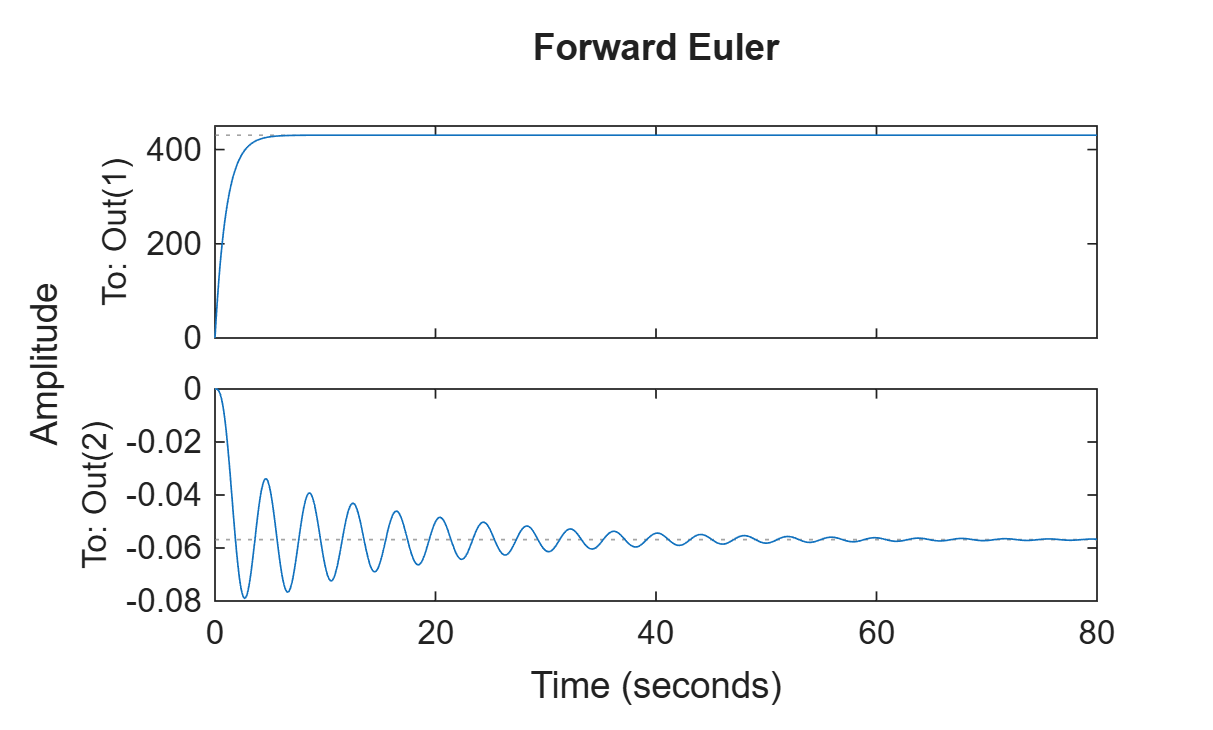

load('SS_7_5_morn.mat')
h = 0.01;
t = 0:h:40;
u = 0.5 * ones(length(t),1);

sys_fe = ss(A,B,C,D,h);
figure;
lsim(sys_fe, u,t);
title("Forward Euler")

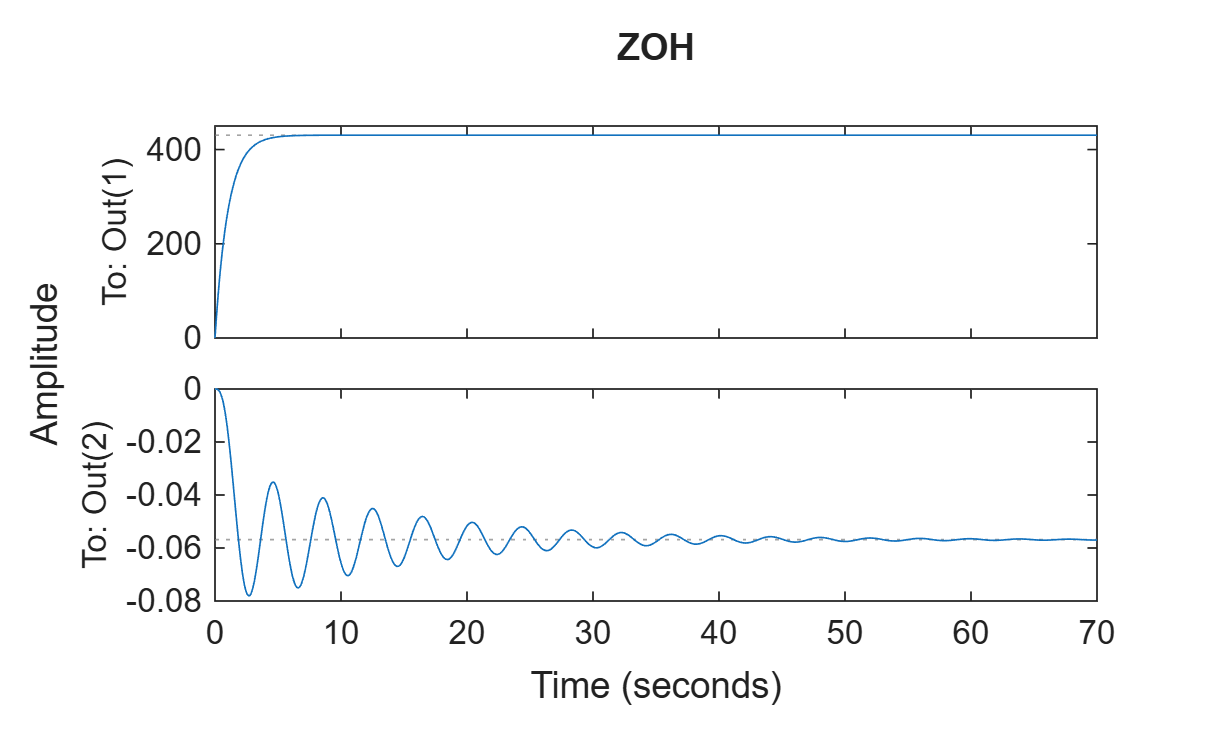


alpha1 = (A(1,1)-1)/h;
alpha2 = A(3,1)/h;
alpha3 = A(3,2)/h;
alpha4 = (A(3,3)-1)/h;
alpha5 = B(1)/h;

A_con = [alpha1 0 0; 0 0 1; alpha2 alpha3 alpha4];
B_con = [alpha5; 0; 0];

sys = ss(A_con,B_con,C,D);
sys_d = c2d(sys, h, 'zoh');
figure;
lsim
title("ZOH")

clearvars -except h
load('step_response.mat')
y1 = angular_velocity.data;
y1 = y1(201:end);
y2 = pendulum_angle.data;
y2 = y2(201:end);

tiledlayout(2,1);

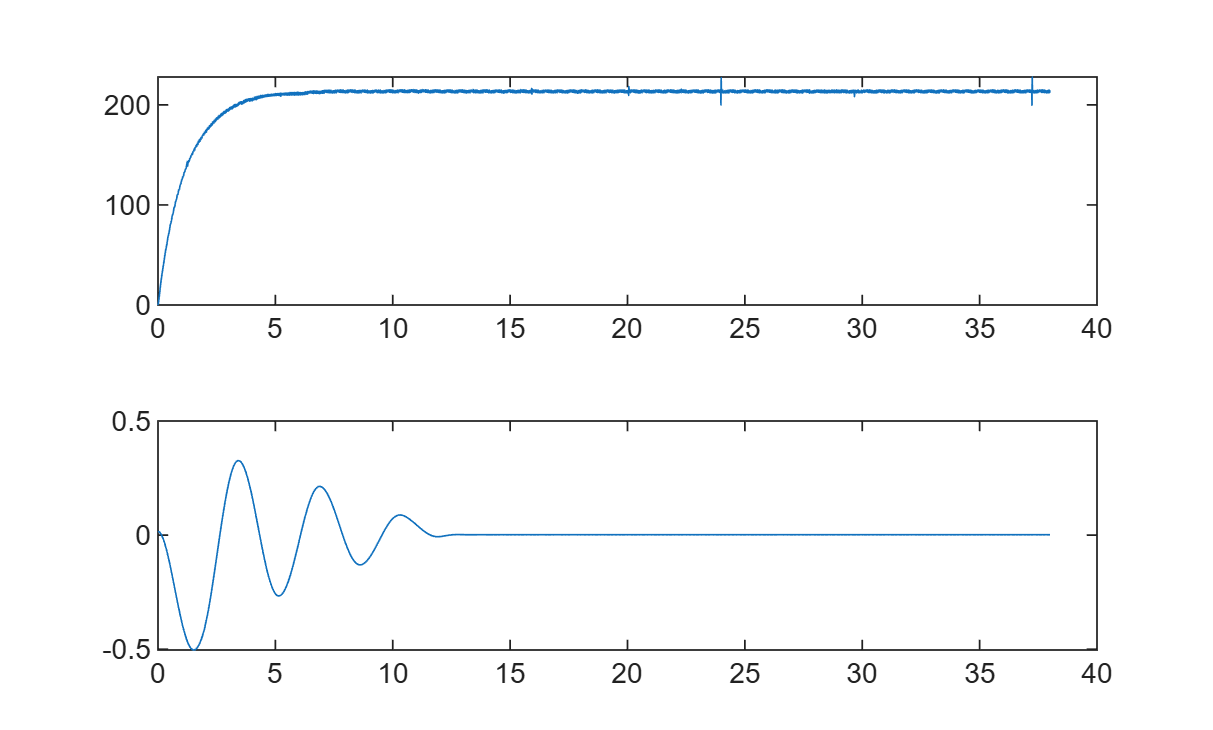

t = 0:h:40-2;
nexttile
plot(t,y1);

nexttile
plot(t,y2);


clear